## Comprobación de resultados

clear

% load resultados1
load resultados2

[YPred,probs] = classify(net,imdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9333

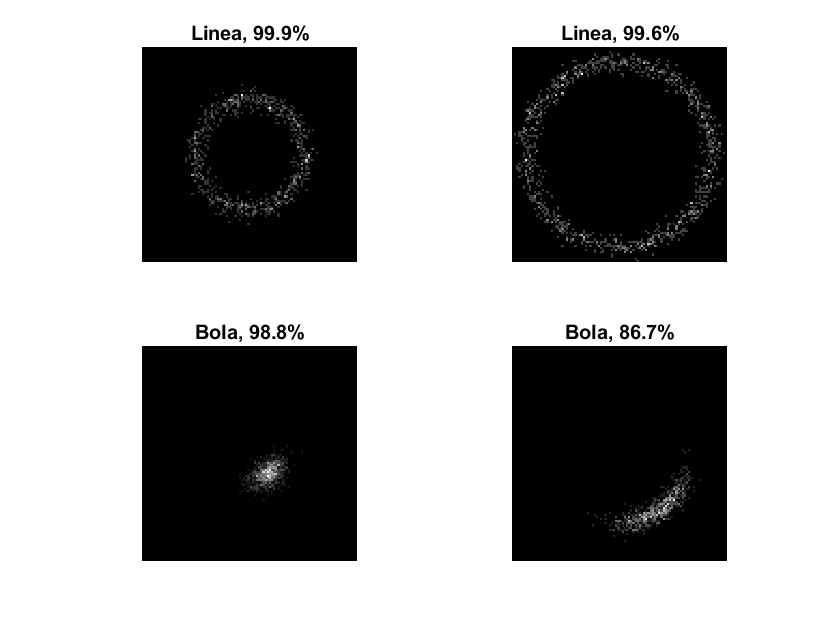

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end